clear

low = sqrt(2) .* [0.602949, 0.266864, -0.078223, -0.016864, 0.026749]';
low = [low(end:-1:2); low];
high = 1/sqrt(2) .* [1.115087, -0.591272, -0.057544, 0.091272]';
high = [high(end:-1:2); high];

low_syn = 1/sqrt(2) .* [1.115087, 0.591272, -0.057544, -0.091272]';
low_syn = [low_syn(end:-1:2); low_syn];
high_syn = sqrt(2) .* [0.602949, -0.266864, -0.078223, 0.016864, 0.026749]';
high_syn = [high_syn(end:-1:2); high_syn];

phi = low * low';
psi_0 = low * high';
psi_1 = high * low';
psi_2 = high * high';

phi_syn = low_syn * low_syn';
psi_0_syn = low_syn * high_syn';
psi_1_syn = high_syn * low_syn';
psi_2_syn = high_syn * high_syn';

samples = readmatrix('cornellTrans.png_11_22_0_9.csv');
sample_1 = reshape(mean(samples(:,1:3),2), [1024, 1024])';
sample_2 = reshape(mean(samples(:,4:6),2), [1024, 1024])';
sample_3 = reshape(mean(samples(:,7:9),2), [1024, 1024])';
sample_4 = reshape(mean(samples(:,10:12),2), [1024, 1024])';

sample_mean = (sample_1 + sample_2 + sample_3 + sample_4) ./ 4;
sample_mean(sample_mean > 1) = 1;

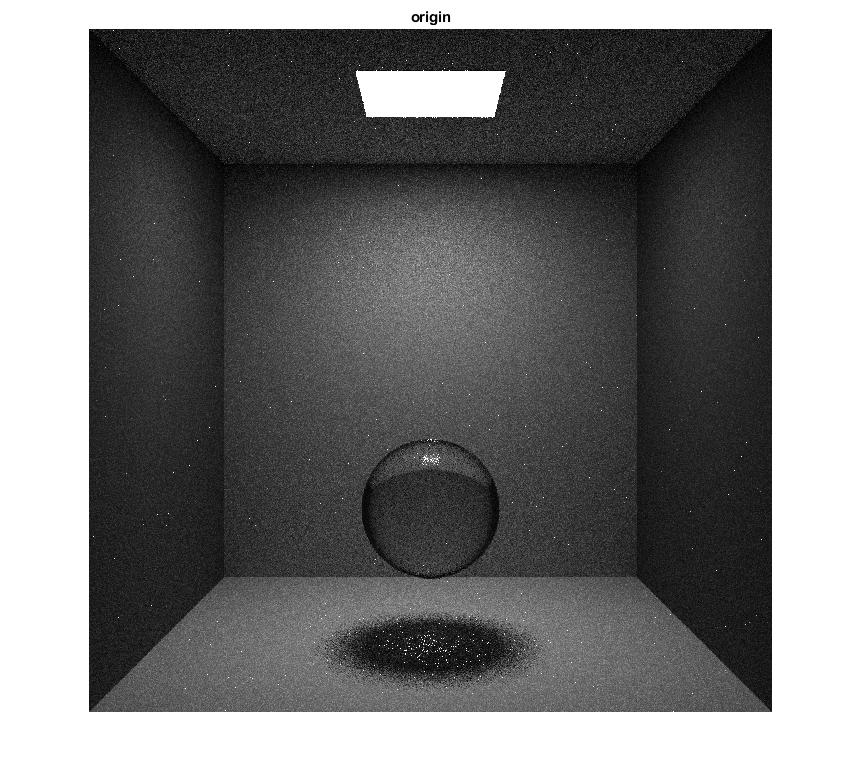

% level1
decomp = cell(5,1);
LL = sample_mean;

figure
imshow(LL);
title("origin")

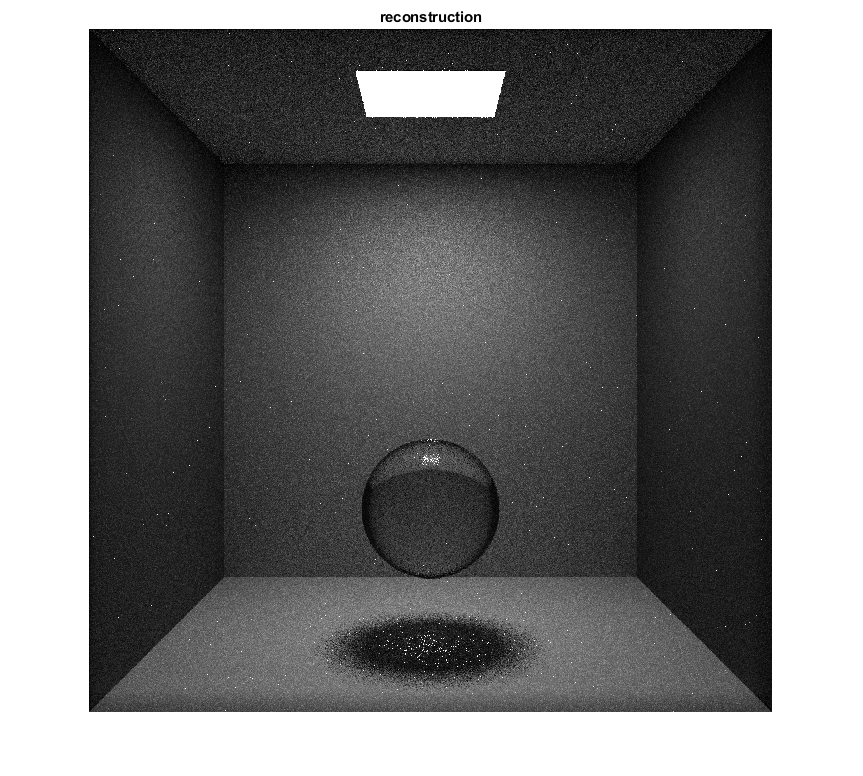


%decomposition
for i = 1 : 5
    [LL, LH, HL, HH] = DWT_conv(LL, phi, psi_0, psi_1, psi_2);
    decomp{i} = cat(3, LH, HL, HH);
end

%reconstruction
for i = 5 : -1 : 1
    LH = decomp{i}(:,:,1);
    HL = decomp{i}(:,:,2);
    HH = decomp{i}(:,:,3);
    LL = IDWT_conv(LL, LH, HL, HH, phi_syn, psi_0_syn, psi_1_syn, psi_2_syn);
end

figure
imshow(LL);
title("reconstruction")

function [LL, LH, HL, HH] = DWT_conv(input, phi, psi_0, psi_1, psi_2)
LL = conv2(input, phi, "same");
LL = LL(1:2:end, 1:2:end);

LH = conv2(input, psi_0, "same");
LH = LH(1:2:end, 2:2:end);

HL = conv2(input, psi_1 , "same");
HL = HL(2:2:end, 1:2:end);

HH = conv2(input, psi_2, "same");
HH = HH(2:2:end, 2:2:end);
end

function result = IDWT_conv(LL, LH, HL, HH, phi_syn, psi_0_syn, psi_1_syn, psi_2_syn)
LL_syn = zeros(size(LL) * 2);
LH_syn = LL_syn;
HL_syn = LL_syn;
HH_syn = LL_syn;

LL_syn(1:2:end, 1:2:end) = LL;
LH_syn(1:2:end, 2:2:end) = LH;
HL_syn(2:2:end, 1:2:end) = HL;
HH_syn(2:2:end, 2:2:end) = HH;

LL_syn = conv2(LL_syn, phi_syn, 'same');
LH_syn = conv2(LH_syn, psi_0_syn, 'same');
HL_syn = conv2(HL_syn, psi_1_syn, 'same');
HH_syn = conv2(HH_syn, psi_2_syn, 'same');

result = LL_syn + LH_syn + HL_syn + HH_syn;

end